clear
% definir las ecuaciones diferenciales
k=1/2;
f = @(t, y) [y(2); (2*y(1)*k)-(2*(y(1))^3)];

% definir el rango de valores para x y y
x = linspace(-1, 1, 7);
y = linspace(-1, 1, 7);

% generar una malla de valores para x y y
[X, Y] = meshgrid(x, y);

% calcular las derivadas en cada punto de la malla
u = zeros(size(X));
v = zeros(size(Y));
t = 0; % tiempo
hola=numel(X);
for i = 1:hola
    Yprime = f(t, [X(i); Y(i)]);
    u(i) = Yprime(1);
    v(i) = Yprime(2);
end


% definir el rango de valores para x y y
x1 = linspace(-1, 1, 30);
y1 = linspace(-1, 1, 30);

% generar una malla de valores para x y y
[X1, Y1] = meshgrid(x1, y1);

% calcular las derivadas en cada punto de la malla
u1 = zeros(size(X1));
v1 = zeros(size(Y1));
t = 0; % tiempo
hola=numel(X1);
for i = 1:hola
    Yprime = f(t, [X1(i); Y1(i)]);
    u1(i) = Yprime(1);
    v1(i) = Yprime(2);
end



% trazar el retrato de fase sin flechas
p=quiver(X1, Y1, u1, v1)

p =   Quiver with properties:

        Color: [0 0.4470 0.7410]
    LineStyle: '-'
    LineWidth: 0.5000
        XData: [30x30 double]
        YData: [30x30 double]
        ZData: []
        UData: [30x30 double]
        VData: [30x30 double]
        WData: []

  Show all properties


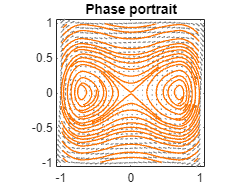

set(p,'Color','#808080');
hold on
l=streamslice(X, Y, u, v, 'noarrows');
%xlabel('x');
%ylabel('y');
axis tight equal;
set(l,'LineWidth',1)
set(l,'Color','#FF7300');
title("Phase portrait")